cd /Users/serg/github_projects/QASS_SVM/data
load iris.mat

%type='c' classification probably
type='c'; 
gam = 1; 
degree = 1;
t=1;
[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'});


[Yht, Zt] = simlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'}, {alpha,b}, Xtest);
err = sum(Yht~=Ytest); 
fprintf('\n on test: #number of missclassified data point = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)


 on test: #number of missclassified data point = 11, error rate = 55.00%


figure; 
plotlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel','preprocess'},{alpha,b});

Start Plotting...finished


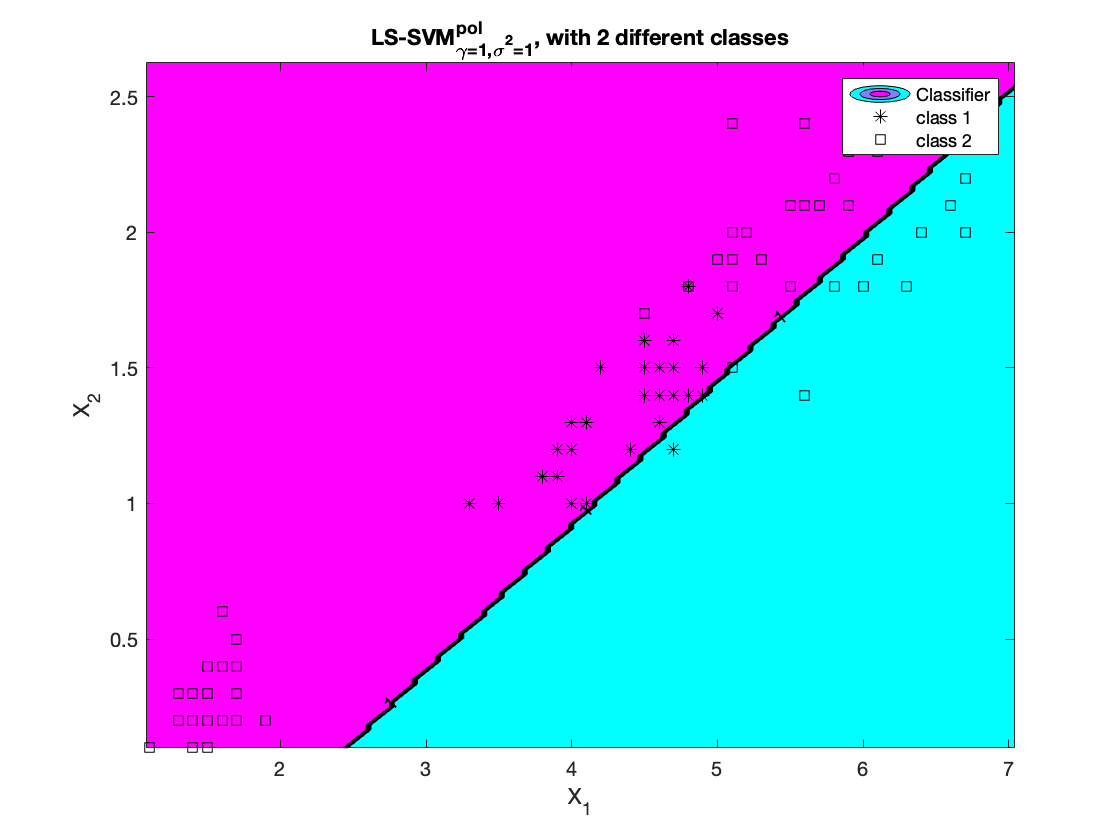

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_131_1.png','Resolution',300)

type='c'; 
gam = 1; 
degree = 2;
t=1;
[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'});


[Yht, Zt] = simlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'}, {alpha,b}, Xtest);
err = sum(Yht~=Ytest); 
fprintf('\n on test: #number of missclassified data point = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)


 on test: #number of missclassified data point = 1, error rate = 5.00%


figure; 
plotlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel','preprocess'},{alpha,b});

Start Plotting...finished


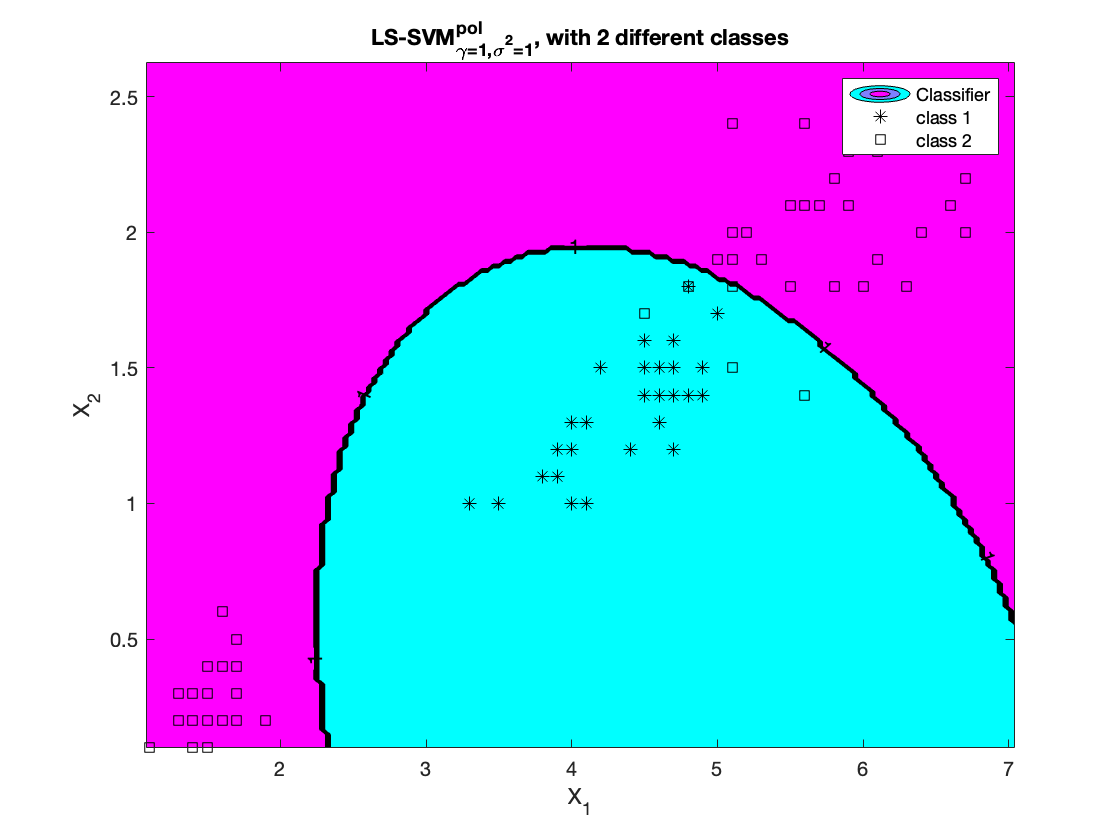

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_131_2.png','Resolution',300)

type='c'; 
gam = 1; 
degree = 3;
t=1;
[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'});


[Yht, Zt] = simlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel'}, {alpha,b}, Xtest);
err = sum(Yht~=Ytest); 
fprintf('\n on test: #number of missclassified data point = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)


 on test: #number of missclassified data point = 0, error rate = 0.00%



figure; 
plotlssvm({Xtrain,Ytrain,type,gam,[t; degree],'poly_kernel','preprocess'},{alpha,b});

Start Plotting...finished


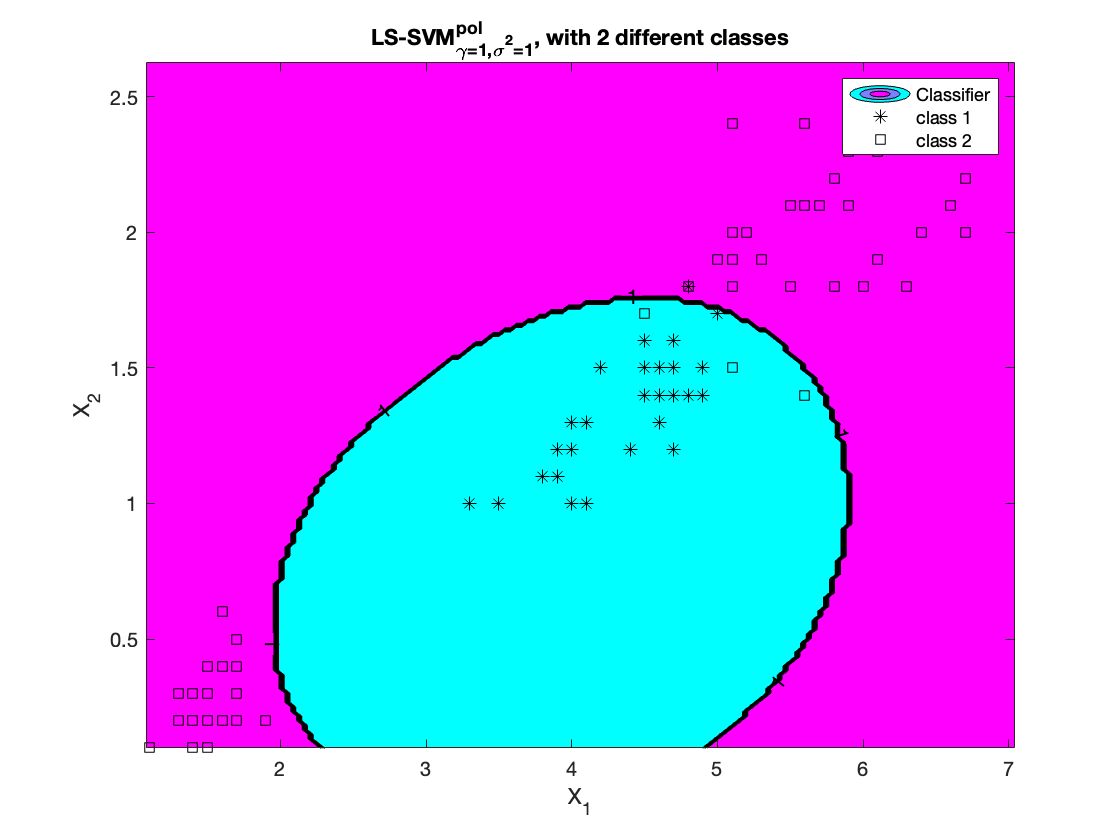

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_131_3.png','Resolution',300)

l_sig=0.001:0.01:20;
gam = 1; 
type='c'; 

err_n=[];
err_p=[];

for sig2=l_sig,

    [alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});
    [Yht, Zt] = simlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'}, {alpha,b}, Xtest);

    err = sum(Yht~=Ytest); 
    err_n= [err_n; err];
    err_p= [err_p; err/length(Ytest)];
    fprintf('\n sigma = %.2f, #number of missclassified data point = %d, error rate = %.2f%%\n', sig2, err, err/length(Ytest)*100)
end


 sigma = 0.00, #number of missclassified data point = 6, error rate = 30.00%

 sigma = 0.01, #number of missclassified data point = 2, error rate = 10.00%

 sigma = 0.02, #number of missclassified data point = 1, error rate = 5.00%

 sigma = 0.03, #number of missclassified data point = 1, error rate = 5.00%

 sigma = 0.04, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.05, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.06, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.07, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.08, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.09, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.10, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.11, #number of missclassified data point = 0, error rate = 0.00%

 sigma = 0.12, #number of missclassified data point = 0, error rate = 0.0

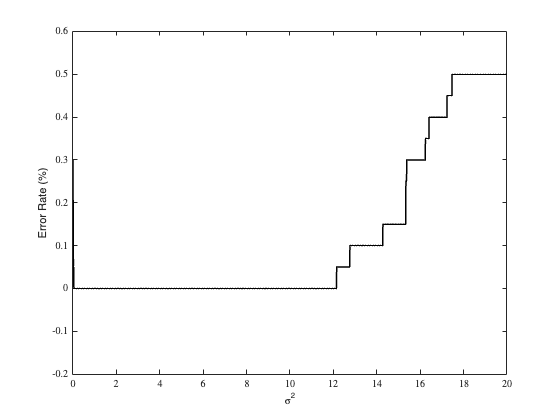

blackColor = [0 0 0];
figure;
plot(l_sig, err_p,'Color', blackColor,'LineWidth',1.5);
xlim([0 20]);
ylim([-0.2 0.6]);
set(gca,'TickLabelInterpreter','latex');
xlabel('\sigma^2');
ylabel('Error Rate (%)');

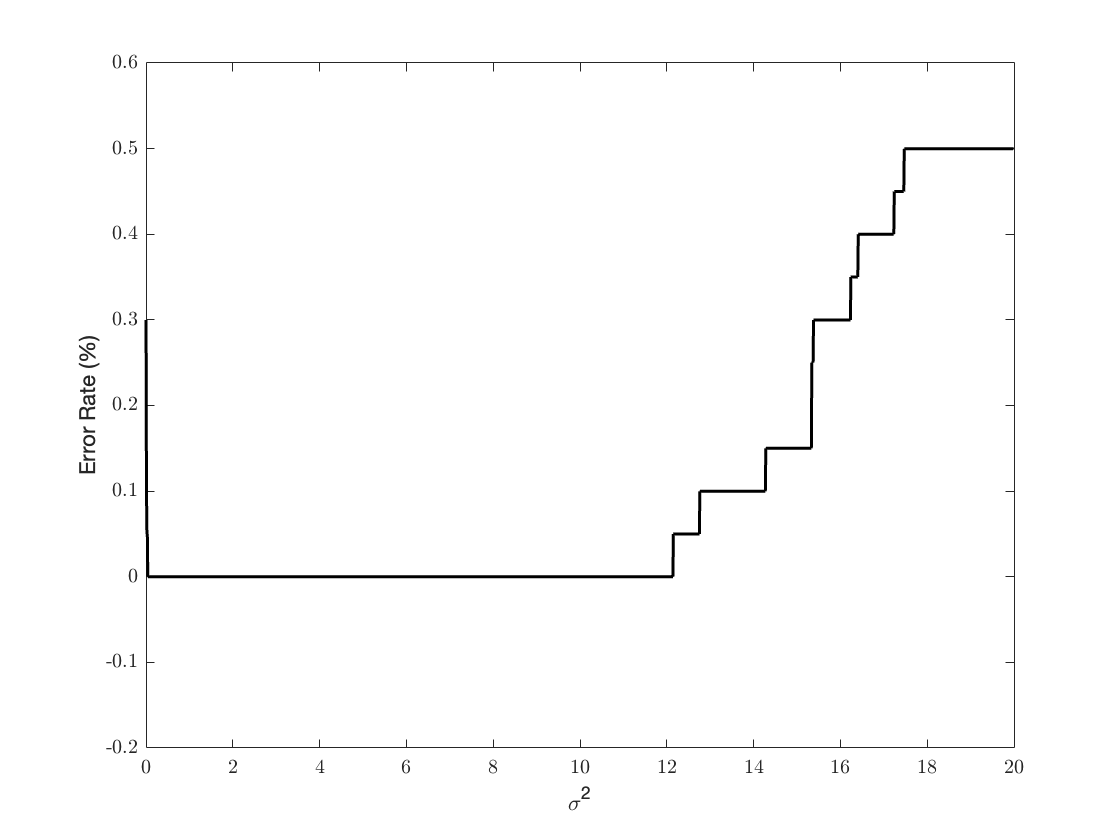

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_131_4.png','Resolution',300)

l_gam=0.01:0.01:20;
sig2 = 6; 
type='c'; 

err_n=[];
err_p=[];

for gam=l_gam,

    [alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});
    [Yht, Zt] = simlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'}, {alpha,b}, Xtest);

    err = sum(Yht~=Ytest); 
    err_n= [err_n; err];
    err_p= [err_p; err/length(Ytest)];
    fprintf('\n gamma = %.2f,  #number of missclassified data point = %d, error rate = %.2f%%\n', gam, err, err/length(Ytest)*100)
end


 gamma = 0.01,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.02,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.03,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.04,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.05,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.06,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.07,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.08,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.09,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.10,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.11,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.12,  #number of missclassified data point = 10, error rate = 50.00%

 gamma = 0.13,  #number of missclassifi

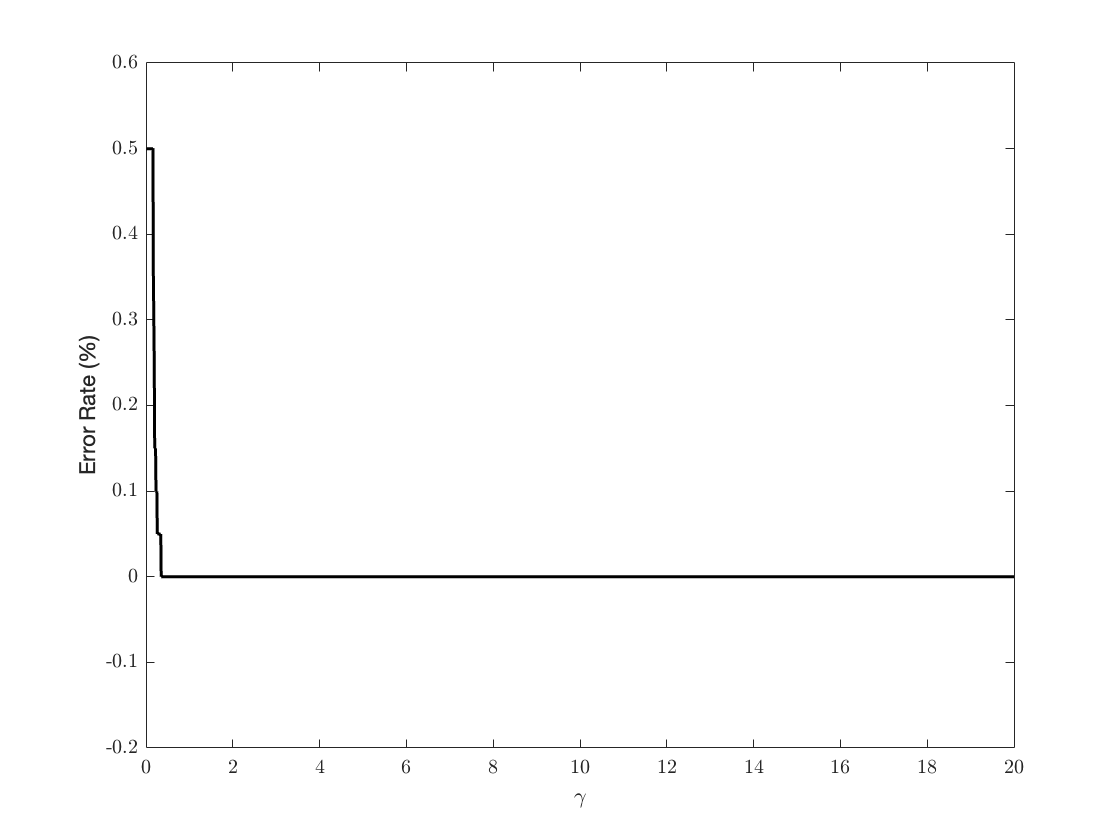

blackColor = [0 0 0];
figure;
plot(l_gam, err_p,'Color', blackColor,'LineWidth',1.5);
%xlim([0 40]);
ylim([-0.2 0.6]);
set(gca,'TickLabelInterpreter','latex');
xlabel('\gamma');
ylabel('Error Rate (%)');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures1/fig1_131_5.png','Resolution',300)